# 3D surface retina model

Use this to illustrate the type of output we might get from PBRT with the mesh implemented onto it.

Demo for Joyce Liao about implications of curving the photoreceptor layer of the retina.  This might be from diseases in the retinal pigment epithelium that displace the photoreceptor layer.

TODO:  [Amsler](https://www.google.com/search?q=ansler+grid&rlz=1C5GCEM_enUS991US991&oq=ansler+grid&aqs=chrome..69i57j0i10i131i433i512l2j0i10i512l7.1889j0j4&sourceid=chrome&ie=UTF-8) grid -  Used in diagnosis

## Build the 3D mesh

Units are microns.

Make spatial samples at 10 micron resolution for the central 20 deg (+/- 10 deg, 300 microns per degree).

% Planar sample positions
row = -3000:10:3000;   % Microns
col = row;
[X, Y] = meshgrid(row,col);

% The retinal curvature is approximated as a sphere around the lens,
% which is 17 mm (1700 microns) away.
radius = 1*1e6;    
Z = -1*sqrt(radius^2 - X.^2 - Y.^2);
Z = Z - max(Z(:));
assert(isreal(Z)) % Check that the solution is real

%% Add a bump at a translated position, T, with size sigma
sigma = 500;
T = [1000 1000];
gaussianBump = exp(-((X-T(1)).^2 + (Y-T(2)).^2)/(2*sigma^2));

% Make the bump size in microns
bumpHeight = 5;
sFactor = 10/max(gaussianBump(:));
Z = Z + sFactor*gaussianBump;

min(Z(:))

ans = -8.9295

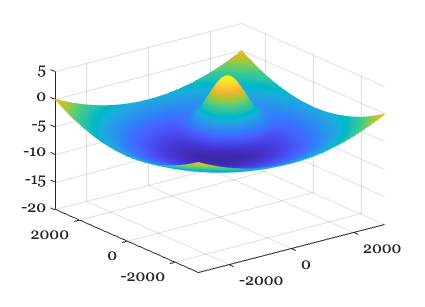


% visualize it
ieNewGraphWin;
mesh(X,Y,Z);
set(gca,'zlim',[-20 bumpSize]);

## Paint an image on the mesh

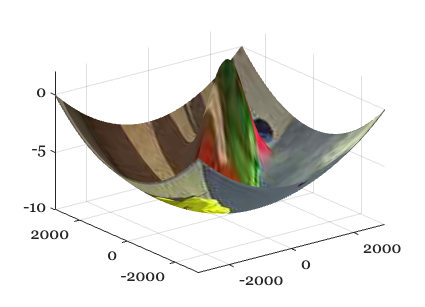

checks = imread('hatsC.jpg');
img2 = imresize(checks,size(X));

ieNewGraphWin;
s = mesh(X,Y,Z,img2);
s.FaceColor = 'flat';

## Make  more test images, like the Amsler grid

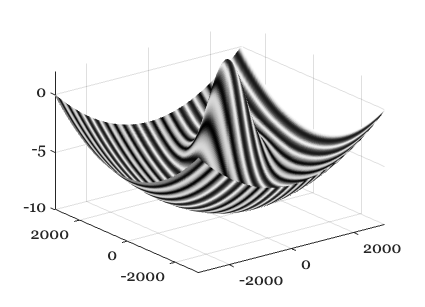

hParams = harmonicP;
hParams.freq = 20;
harmonic = imageHarmonic(hParams);
harmonic = imresize(harmonic,size(X));
s = mesh(X,Y,Z,harmonic);
s.FaceColor = 'flat';
colormap(gray);

## Checkerboard

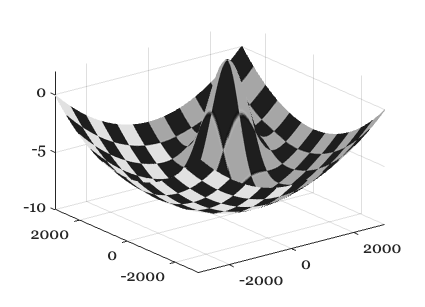

checks = checkerboard(20,6,6);
checks = imresize(checks,size(X));

ieNewGraphWin;
s = mesh(X,Y,Z,checks);
s.FaceColor = 'flat';
colormap(gray);

## The letter g

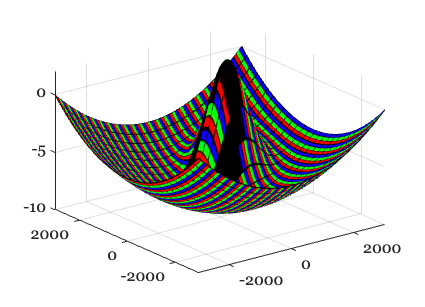

scene  = sceneCreate('letter');
letter = sceneGet(scene,'rgb');
letter = imresize(letter,size(X));

ieNewGraphWin;
s = mesh(X,Y,Z,letter);
s.FaceColor = 'flat';

## Measure distance

But we need to measure the distance along the surface of a mesh in Matlab.

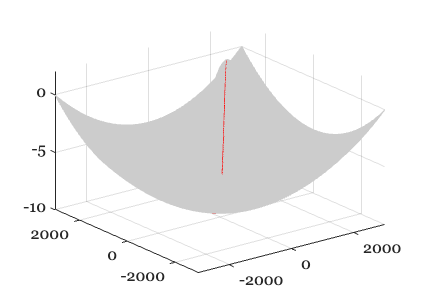

% Here is a simple approach
%
% https://www.mathworks.com/support/search.html/answers/843605-geodesic-distances-on-a-curved-surface.html?fq%5B%5D=asset_type_name:answer&fq%5B%5D=category:matlab/computational-geometry&page=1 

pt1 = [1000 1000];
pt2 = [-1000,-1000];

x1 = linspace(pt1(1),pt2(2),100);
y1 = linspace(pt1(1),pt2(2),100);
z1 = interp2(X,Y,Z,x1,y1);

% Show the path.  It is not necessarily a geodesic, however.
surf(X,Y,Z,'edgecolor',[1 1 1]*0.8)
line(x1,y1,z1,'color','red','linewidth',2)


% Puzzled about the lengths
L = sum(sqrt(diff(x1).^2+diff(y1).^2+diff(z1).^2))*1e-3 % mm

L = 2.8285


% The distance along the plane underneath - For this geometry the bump
% is very small.  So the distance difference is small.  Use a better
% example.
D = norm(pt2 - pt1)*1e-3

D = 2.8284


%{
% Two points in x,y.  
pt1 = [-3,2];
pt2 = [-1,1];

% Here is the surface
[x,y,z] = peaks(20);            % surface

% curve coordinates
x1 = linspace(pt1(1),pt1(2),20);
y1 = linspace(pt2(1),pt2(2),20);
z1 = interp2(x,y,z,x1,y1);

% Show the path.  It is not necessarily a geodesic, however.
surf(x,y,z,'edgecolor',[1 1 1]*0.8)
line(x1,y1,z1,'color','red','linewidth',2)

% The distance along the surface
L = sum(sqrt(diff(x1).^2+diff(y1).^2+diff(z1).^2))

% The distance along the plane underneath
D = norm(pt2 - pt1)
%}